## Assignment 9

####     Part 1

slowmotion = load("slowmotion.mat");

IQ = slowmotion.iq;
s = slowmotion.s;
sm_framerate = s.Framerate_fps;
sm_depthIncrease_iq = s.iq.DepthIncrementIQ_m;
sm_startDepth_iq = s.iq.StartDepthIQ_m;
sm_num_beams_iq = s.iq.BeamsIQ;
sm_samples_iq = s.iq.SamplesIQ;
sm_frames_iq = s.iq.FramesIQ;
tissue = slowmotion.tissue;
sm_gain_iq = s.iq.feflowgain_dB;
sm_dyn_iq = s.iq.DynRange_dB;

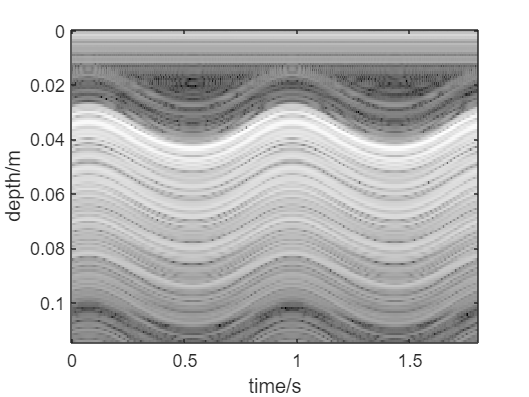

middle_beam = squeeze(IQ(:,4,:));
%since y axis is the samples and x axis is the frames
y_axis = sm_startDepth_iq:sm_depthIncrease_iq:(sm_samples_iq-1)*sm_depthIncrease_iq + sm_startDepth_iq;
x_axis = 0:1/sm_framerate:(sm_frames_iq-1)*1/sm_framerate;
%im = imagelog(abs(middle_beam),sm_gain_iq,sm_dyn_iq);
%imagesc(im, 'XData',x_axis,'YData',y_axis);
figure(1)
imagesc(x_axis, y_axis, 20*log10( abs( middle_beam) ) )
%caxis([-sm_dyn_iq 0]-sm_gain_iq)
%imagesc(20*log10(abs(middle_beam)),'XData',x_axis,'YData',y_axis);

%axis('image');
ylabel('depth/m');
xlabel('time/s');
axis on;
colormap(gray(255));

R = 0.0075; %in meter,estimated from the image
T = 0.9; %in seconds,estimated from the image
t0 = 1; %in seconds, estimated from the image
t = x_axis;
L = 0.1

L = 0.1000

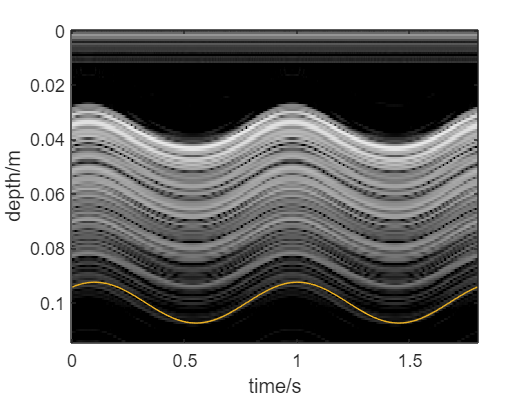

r = -R*cos(2*pi*(t-t0)/T) + L;
figure(2)
imagesc(x_axis, y_axis, 20*log10( abs( middle_beam) ) )
hold on;
dyn = 40;
gain = -90;
caxis([-dyn 0]-gain)
%imagesc(20*log10(abs(middle_beam)),'XData',x_axis,'YData',y_axis);
plot(t,r)
%axis('image');
ylabel('depth/m');
xlabel('time/s');
axis on;
colormap(gray(255));

#### Part 2

r_der = 2*pi*R/T *sin(2*pi*(t-t0)/T);

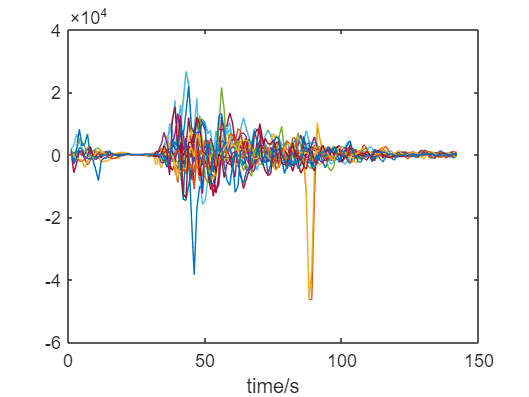

figure(3);
plot(t,r_der);
xlabel('time/s');

x = IQ(:,4,42);
y = IQ(:,4,43);

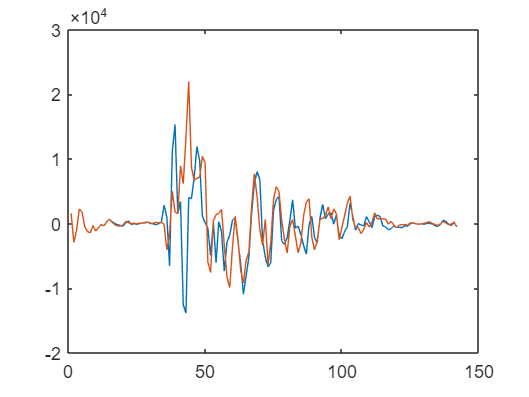

x_RF = iq2rf(x,s.iq.fDemodIQ_Hz,350,200);
y_RF = iq2rf(y,s.iq.fDemodIQ_Hz,350,200);
clf("reset");
figure(4);
plot(x_RF);
hold on;
plot(y_RF);